# 测试

clc
clear
close all
addpath("src\");

## C-W交会

args.n = 0.00111; % rad/s
args.f = 0.1; % N
tf = 2000.; % s
x0 = [2200., 8000., 100., 0., 0., 0.]';  % m, m/s
xf = zeros(6, 1);
step = 1;

### 间接法

#### 初值

[t, sol0] = ode45(@(t, x) CwFuelOpt(t, x, args), 0 : step : tf, [x0; 0.1 * ones(6, 1)]);
sol0 = [t, sol0];

#### 能量最优

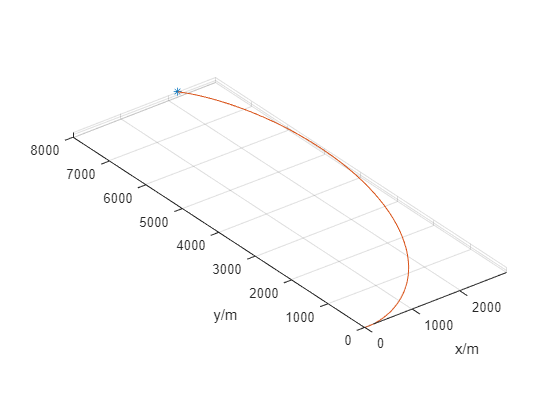

% [sol] = IndirOpt(x0, xf, tf, @CwFixedFuel);
% [sol] = IndirOpt(x0, xf, sol0, @(t, x) CwFuelOpt(t, x, args));
[sol] = IndirOpt(x0, xf, sol0, @(t, x) CwFuel2Opt(t, x, args));
x = sol.y';
figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

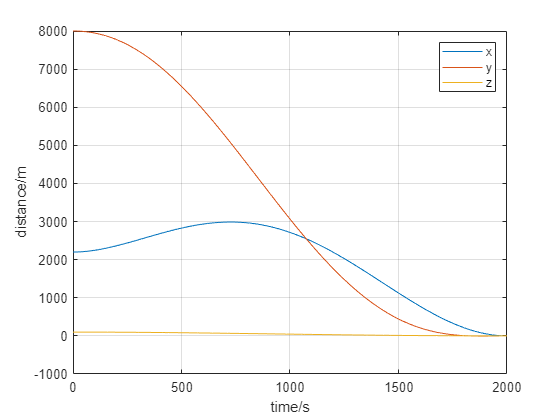

figure
plot(t, x(:, 1 : 3))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')

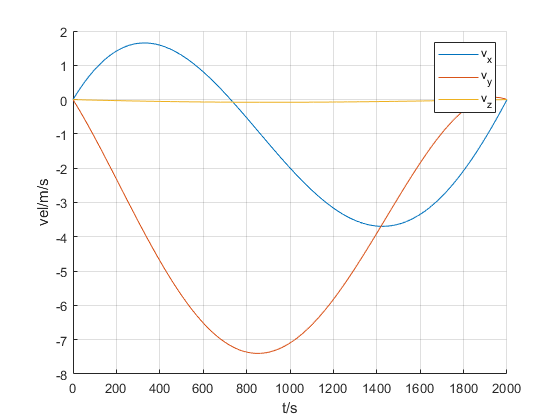

figure
hold on
plot(t, x(:, 4 : 6))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

#### 时间最优

sol0 = [sol0 tf * zeros(length(t), 1)];
[sol] = CwTimeIndirOpt(x0, xf, sol0, args)

错误使用 bvp4c (第 197 行)
无法求解配置方程 - 遇到了奇异的 Jacobian 矩阵。

出错 CwTimeIndirOpt (第 10 行)
sol = bvp4c(@(t, x) CwTimeOpt(t, x, args), @(xa, xb) BoundCon(xa, xb, x0, xf, args), solinit);

x = sol.y';
figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off
figure
plot(t, x(:, 1 : 3))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
figure
hold on
plot(t, x(:, 4 : 6))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

#### 燃料最优

% sol0 = [t, x];
% [sol] = IndirOpt(x0, xf, sol0, @(t, x) CwFixedFuel(t, x, args));

错误使用 bvp4c (第 197 行)
无法求解配置方程 - 遇到了奇异的 Jacobian 矩阵。

出错 IndirOpt (第 10 行)
sol = bvp4c(DynEq, @(xa, xb) BoundCon(xa, xb, x0, xf), solinit);

% x = sol.y';
% figure
% plot3(x0(1), x0(2), x0(3), '*')
% hold on
% plot3(x(:, 1), x(:, 2), x(:, 3))
% grid on
% axis equal
% xlabel('x/m')
% ylabel('y/m')
% zlabel('z/m')
% hold off
% figure
% plot(t, x(:, 1 : 3))
% grid on
% legend('x', 'y', 'z')
% xlabel('time/s')
% ylabel('distance/m')
% figure
% hold on
% plot(t, x(:, 4 : 6))
% grid on
% legend('v_x', 'v_y', 'v_z')
% xlabel('t/s')
% ylabel('vel/m/s')
% hold off